# Dax performance exercise

### The overall goal of this exercise is to determine the performance (the yearly average relative increase) of the DAX from 1987.

There for we need to 

- import the data

- manipulate the data

- find a fit function

- use a fitting routine and find the percentage the DAX has grown in average each year

- plot and check the data

First step: Clear you workspace, command window and close all plots

close all
clear all
clc 

Task: Import the data  of DAXOpening.csv; name the arrays the same way as in the .csv file.

data = readtable('DAXOpening.csv');
date = table2array(data(:,1));
DAXPoints = table2array(data(:,2)); % stock price

The following functions turns the date into a dezimal date. Feel free to look up the function on the internet:

dateNumber = datenum(string(date),'dd-mmm-yyyy');


Now plot the data (with the date "style" of the .csv file). What do you notice? (hint: look at the x-axis) does it makes sense to fit the data right away? Whats the time scale (compare it to the original date)? Otherwise manipulate the x values the right way. 

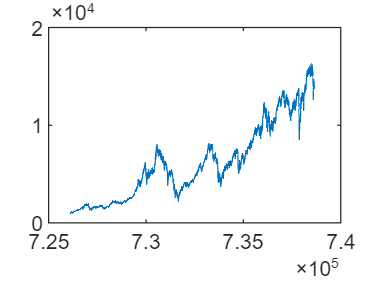

plot(dateNumber, DAXPoints)


dateNumber = dateNumber-dateNumber(1)+1;
dateNumber = dateNumber/365;


Since the data is set, we can now take a look at the correct fitting function. In our case this is: a*(b)^t. Create the symbolic function:

fun = @(x,dateNumber) x(1).*(x(2)).^(dateNumber); % function for fitting


Now you need to think of some initial values. (What makes sense for a yield each year?).

Use the lsqcurvefit() function to find the value.

x0 = [2000,1.05]; % initial values

x = lsqcurvefit(fun,x0,dateNumber,DAXPoints,[1 1],[5000 1.2]);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Finally plot the data and the fit, to see if the fit was good. To make it a little prettier, add some labels() etc.

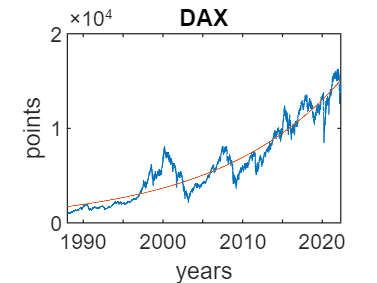

%% Plotting section
plot(date, DAXPoints)
hold on
plot(date, fun(x, dateNumber))
title('DAX')
xlabel('years')
ylabel('points')